clear;clc;close all;
syms x y z;
z=(x-y-3)*(x-y+3)*(x+y-1)

$$z = -\left(x+y-1\right)\,\left(x-y+3\right)\,\left(-x+y+3\right)$$

expand(z)

$$ans = x^{3}-x^{2}\,y-x^{2}-x\,y^{2}+2\,x\,y-9\,x+y^{3}-y^{2}-9\,y+9$$

diff(z,x)

$$ans = \left(x+y-1\right)\,\left(x-y+3\right)-\left(x+y-1\right)\,\left(-x+y+3\right)-\left(x-y+3\right)\,\left(-x+y+3\right)$$

expand(diff(z,x))

$$ans = 3\,x^{2}-2\,x\,y-2\,x-y^{2}+2\,y-9$$

diff(z,y)

$$ans = \left(x+y-1\right)\,\left(-x+y+3\right)-\left(x+y-1\right)\,\left(x-y+3\right)-\left(x-y+3\right)\,\left(-x+y+3\right)$$

expand(diff(z,y))

$$ans = -x^{2}-2\,x\,y+2\,x+3\,y^{2}-2\,y-9$$

figure;hold on;grid on;set(gca,'fontname','メイリオ','fontsize',14)
fcontour(diff(z,x),'LevelList',0,'LineColor','b');
fcontour(diff(z,y),'LevelList',0);
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
title('$z(x,y)=0$','Interpreter','latex');

eq1 = diff(z,x)==0;
eq2 = diff(z,y)==0;

solVal=solve([eq1;eq2])

solVal = フィールドをもつ struct :
    x: [2×1 sym]
    y: [2×1 sym]


solVal.x

$$ans = \left[\begin{array}{c} 2\\ -1 \end{array}\right]$$

solVal.y

$$ans = \left[\begin{array}{c} -1\\ 2 \end{array}\right]$$

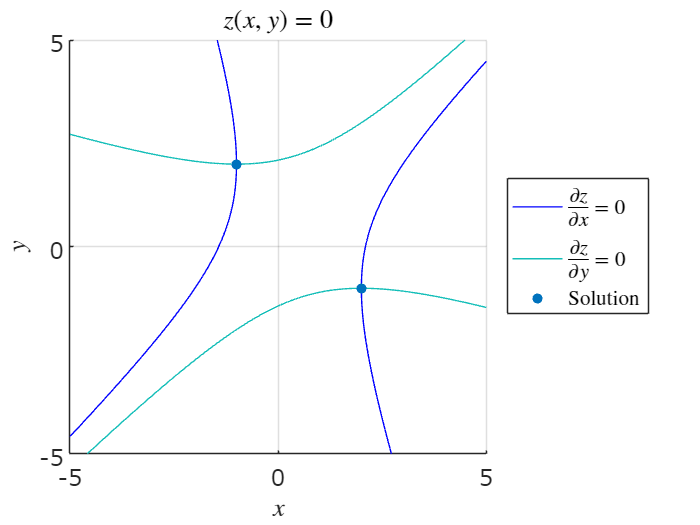

scatter(solVal.x, solVal.y,'filled');
legend({'$\frac{\partial z}{\partial x}=0$', ...
    '$\frac{\partial z}{\partial y}=0$', ...
    'Solution'},'Interpreter','latex', ...
    'Location','eastoutside');
exportgraphics(gcf,'fig_Exercise_ChapA02-1.pdf');

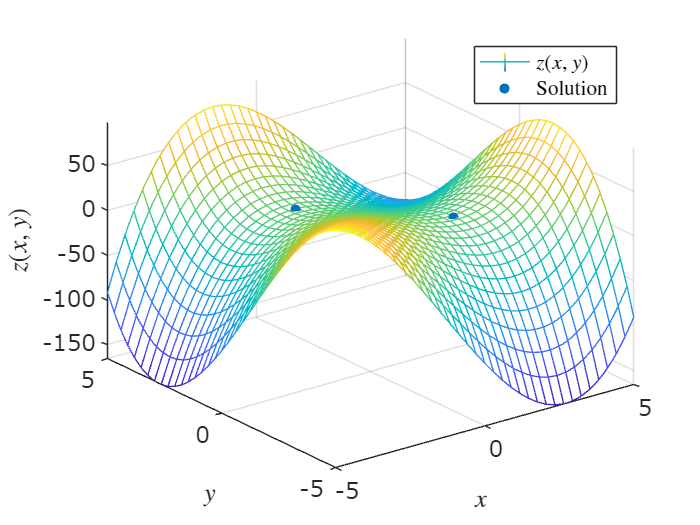


figure;
fmesh(z);
hold on;grid on;set(gca,'fontname','メイリオ','fontsize',14);

zVal=subs(z,{x,y},{solVal.x,solVal.y});
scatter3(solVal.x, solVal.y, zVal,'filled');
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z(x,y)$','Interpreter','latex');
legend({'$z(x,y)$','Solution'},'Interpreter','latex','Location','best')
exportgraphics(gcf,'fig_Exercise_ChapA02-2.pdf');